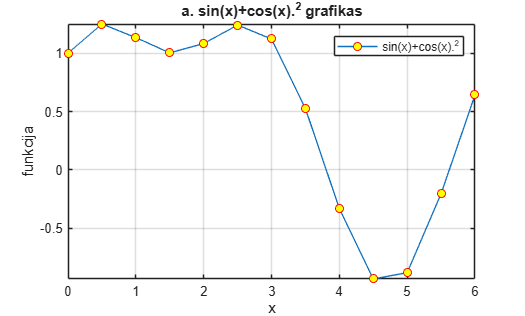

%Dominykas Juršys Edif-25/2 2026-09-28
close all;
clear;
%a) dvimatis grafikas
x = 0:0.5:2*pi;
y=sin(x)+cos(x).^2;
figure(1);
plot(x,y,'-o', 'MarkerEdgeColor','r','MarkerFaceColor','y')
xlabel('x');
ylabel('funkcija')
legend('sin(x)+cos(x).^2')
title('a. sin(x)+cos(x).^2 grafikas')
axis([min(x) max(x) min(y) max(y)]);
grid on

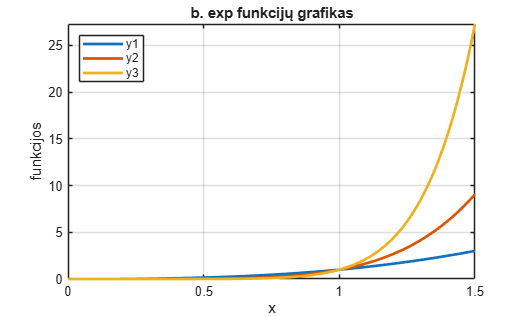

%b)
figure(2);
x1=0:0.01:1.5;
y1=x1.^exp(1);
y2=x1.^(2*exp(1));
y3=x1.^(3*exp(1));
plot(x1,y1,'LineWidth',2);
hold on;
plot(x1,y2,'LineWidth',2);
plot(x1,y3,'LineWidth',2);
grid on;
axis([min(x1) max(x1) min(y3) max(y3)]);
xlabel('x');
ylabel('funkcijos');
legend('y1','y2','y3', 'Location','northwest');
title('b. exp funkcijų grafikas')
hold off;

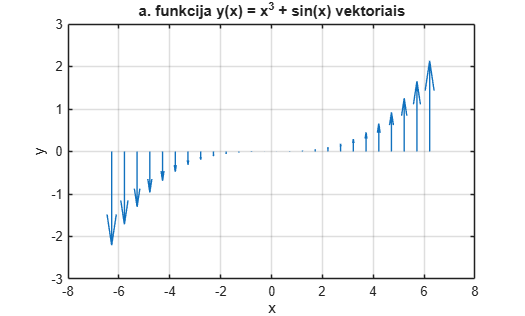

%x taskai 0 ir 1 yra bendri funkcijoms.
%a) spec. grafikas
x2=-2*pi:0.5:2*pi;
y4=x2.^3+sin(x2);
figure(3);
a=zeros(size(x2));
quiver(x2, a, a, y4);
xlabel('x');
ylabel('y');
title('a. funkcija y(x) = x^3 + sin(x) vektoriais');
grid on;

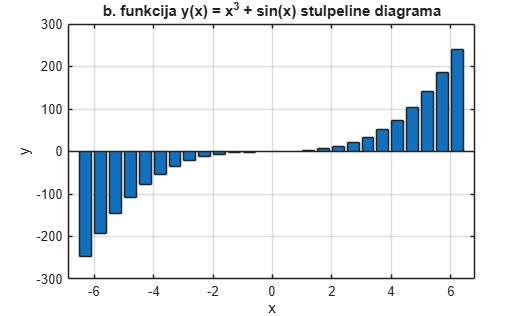

%b)
figure(4);
bar(x2,y4);
xlabel('x');
ylabel('y');
title('b. funkcija y(x) = x^3 + sin(x) stulpeline diagrama');
grid on;

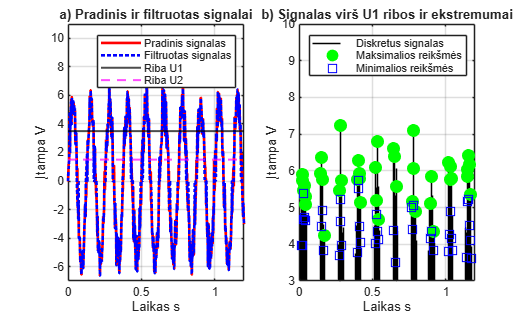

%papildoma
t=0:0.002:1.2;
s=5.5*sin(2*pi*8*t);
n = 0.8 * randn(size(t));
S = s+n;
a = S(S>3.5);
S_fil = S;
S_fil(abs(S)<1.5)=0;
S_u1 = S;
S_u1(S <= 3.5) = NaN;
figure(5);
subplot(1,2,1);
plot(t,S,'r-','LineWidth',2);
hold on;
plot(t,S_fil,'b:','LineWidth',2);
yline(3.5, 'k-', 'LineWidth', 1.5);
yline(1.5, 'm--', 'LineWidth', 1.5);
xlabel('Laikas s');
ylabel('Įtampa V');
title('a) Pradinis ir filtruotas signalai');
grid on;
axis([0, 1.2, -7, 11]);
legend({'Pradinis signalas', 'Filtruotas signalas', 'Riba U1', 'Riba U2'}, 'Location', 'northeast');
subplot(1, 2, 2);
stem(t, S_u1, 'k', 'Marker', 'none');
hold on;
[p_max, l_max] = findpeaks(S_u1); 
[p_min, l_min] = findpeaks(-S_u1);
plot(t(l_max), p_max, 'go', 'MarkerSize', 9, 'MarkerFaceColor', 'g');
plot(t(l_min), -p_min, 'bs', 'MarkerSize', 8);
xlabel('Laikas s');
ylabel('Įtampa V');
title('b) Signalas virš U1 ribos ir ekstremumai');
grid on;
legend({'Diskretus signalas', 'Maksimalios reikšmės', 'Minimalios reikšmės'}, 'Location', 'northeast');
axis([0, 1.2, 3, 10]);